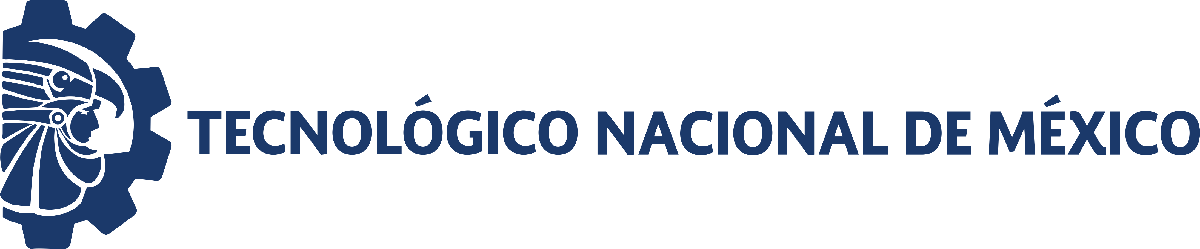                                 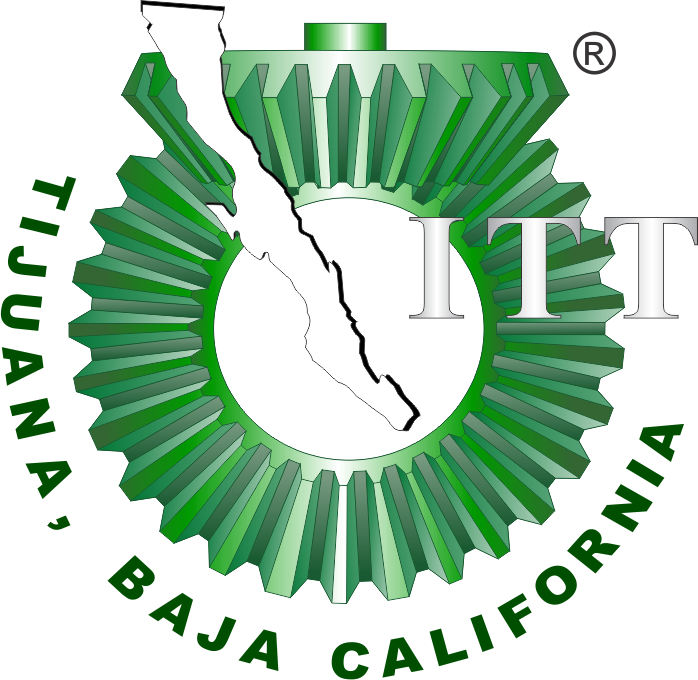

# Práctica dos: Sistema respiratorio

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

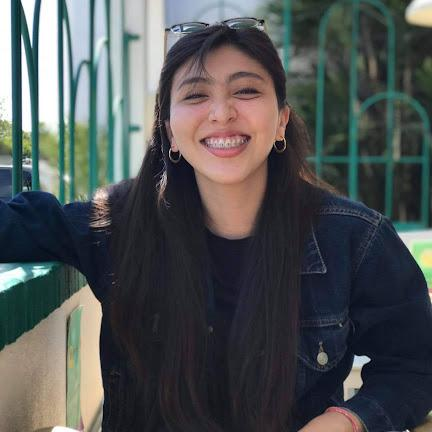

Nombre del alumno: Kenya Fernanda Rodríguez Castro 

Número de control: 20213058

Correo institucional: kenya.rodríguez201@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'SistemaP2';
open_system(file);
parameters.Stoptime = '30';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
Controlador = 'PID';

set_param('SistemaP2/PID Controller','P','173.1126');
set_param('SistemaP2/PID Controller','I','4047.8160');
set_param('SistemaP2/PID Controller','D','0.8218');
set_param('SistemaP2/PID Controller','N','16702.4936');

## Señal Normal (Control)

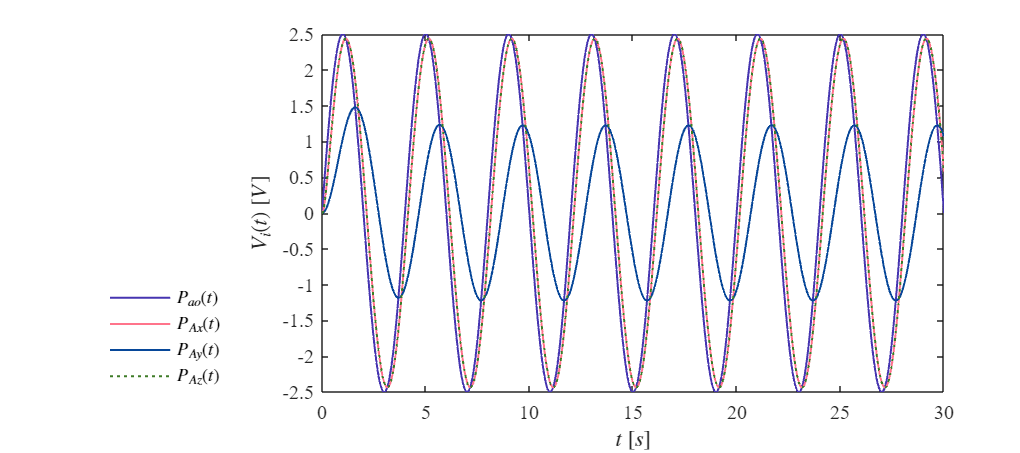

Signal = 'Normal';
set_param('SistemaP2/Pao(t)','sw','0');
N = sim(file,parameters);
plotsignals(N.t,N.Pao,N.PAx,N.PAy,N.PAz,Signal)

## Señal Anormal (Caso)

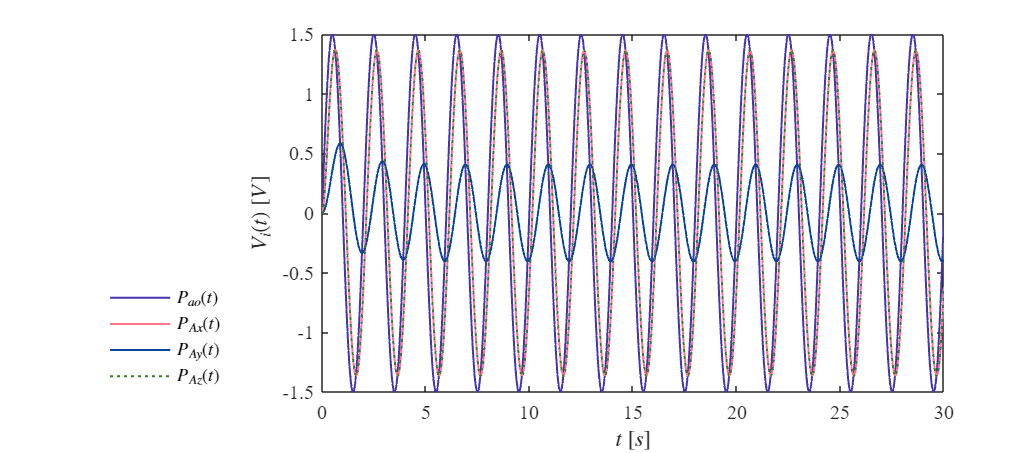

Signal = 'Anormal';
set_param('SistemaP2/Pao(t)','sw','1')
A = sim(file,parameters);
plotsignals(A.t,A.Pao,A.PAx,A.PAy,A.PAz,Signal)

## Funcionamiento de Señales

function plotsignals(t,Pao,PAx,PAy,PAz,Signal)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    
    Morado = [70/255,53/255,177/255];
    Verde =  [62/255,123/255,39/255];
    Rosa = [255/255,116/255,139/255];
    Azul = [7/255,71/255,153/255];
    
    hold on; grid off; box on 

    plot(t,Pao,'LineWidth',1,'Color',Morado)
    plot(t,PAx,'LineWidth',1,'Color',Rosa)
    plot(t,PAy,'LineWidth',1,'Color',Azul)
    plot(t,PAz,':','LineWidth',1,'Color',Verde)

    xlabel('$t$ $[s]$', 'Interpreter','Latex','FontSize',11)
    ylabel('$V_i(t)$ $[V]$', 'Interpreter','Latex','FontSize',11)
    
    L = legend('$P_{ao}(t)$','$P_{Ax}(t)$','$P_{Ay}(t)$','$P_{Az}(t)$');
    set(L,'Interpreter','Latex','Location','southwestoutside','Box','Off')

    if Signal == "Normal"
        xlim([0,30]); xticks(0:5:30)
        ylim([-2.5,2.5]); yticks(-2.5:0.5:2.5)
    elseif Signal == "Anormal"
        xlim([0,30]); xticks(0:5:30)
        ylim([-1.5,1.5]); yticks(-1.5:0.5:1.5)
    end
    
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
end